Variables

g = 9.8; % m/s^2, down
m = 123 / 1000; % kg
M = ((368 + 63) / 1000) - m; % kg
L = 18.6 / 100; % m
b = 0.3; % N/m/s (coeff. friction)

System Definition

A = [0 1 0 0; 
   0 -b/M g*m/M 0; 
   0 0 0 1; 
   0 -b/(M*L) g*(M+m)/(M*L) 0];

B = [0; 1/M; 0; 1/(M*L)];

C = [1 0 0 0];

D = 0;

states = {'x' 'x_dot' 'phi' 'phi_dot'};
inputs = {'u'};
outputs = {'x'};

sys = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

sys =
 
  A = 
                  x    x_dot      phi  phi_dot
   x              0        1        0        0
   x_dot          0   -0.974    3.914        0
   phi            0        0        0        1
   phi_dot        0   -5.237    73.73        0
 
  B = 
                u
   x            0
   x_dot    3.247
   phi          0
   phi_dot  17.46
 
  C = 
            x    x_dot      phi  phi_dot
   x        1        0        0        0
 
  D = 
      u
   x  0
 
Continuous-time state-space model.



Transfer Function

systf = tf(sys)

systf =
 
  From input "u" to output "x":
     3.247 s^2 + 2.019e-14 s - 171.1
  -------------------------------------
  s^4 + 0.974 s^3 - 73.73 s^2 - 51.32 s
 
Continuous-time transfer function.



Stability

eigenA = eig(A)

eigenA =          0
   -8.7389
   -0.6942
    8.4591


Controllability

bigC = ctrb(A,B);
rank(bigC)

ans = 4

Observability

bigO = obsv(A,C);
rank(bigO)

ans = 4

Gains

% Kalman Filter
Qkf = 1e5; % if large, FAST Response, expensive for actuators
Rkf = 1e0; % if large, SLOW Response, cheap for actuators
[kf,Lkf,P] = kalman(sys,Qkf,Rkf); % solve A.R.E.
Akf = A-C*Lkf;
x_hat = ss(Akf,B,C,D);

% LQR
Q = [12 0 0 0;
    0 1 0 0;
    0 0 102 0;
    0 0 0 10];
R = .045;
K = lqr(sys,Q,R)

K =   -16.3299  -18.3591   95.3880   18.6422


A-B*K

ans = 	1.0e+03 *

         0    0.0010         0         0
    0.0530    0.0586   -0.3058   -0.0605
         0         0         0    0.0010
    0.2850    0.3152   -1.5913   -0.3254


sysLqr = ss(A-K*B,B,C,D)

sysLqr =
 
  A = 
           x1      x2      x3      x4
   x1  -265.8  -264.8  -265.8  -265.8
   x2  -265.8  -266.8  -261.9  -265.8
   x3  -265.8  -265.8  -265.8  -264.8
   x4  -265.8    -271  -192.1  -265.8
 
  B = 
          u1
   x1      0
   x2  3.247
   x3      0
   x4  17.46
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



u = -K*[0;0;pi+.1;0]

u = -309.2089

Klqg = lqr(x_hat,Q,R)

Klqg =    68.6958   80.5405 -157.5973    1.2124



sysC = ss(Akf-B*Klqg,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);

Closed Loop Responses

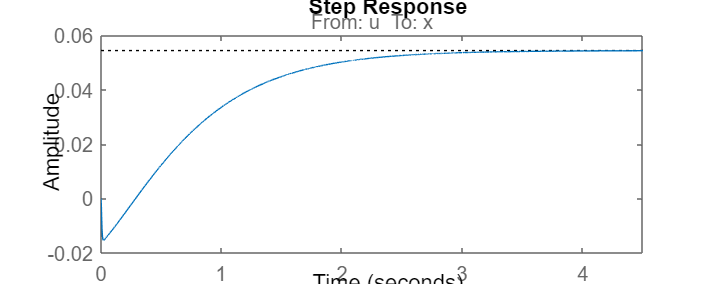

step(sysC)

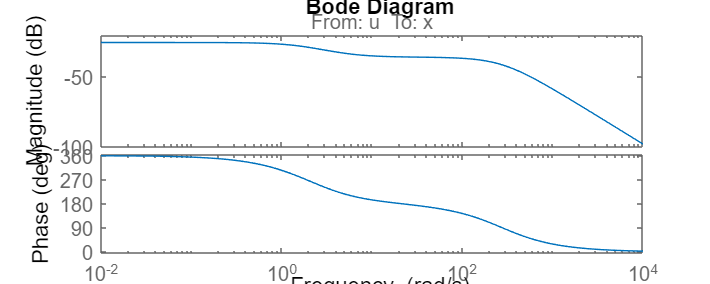

bodeplot(sysC)

Closed Loop Simulation

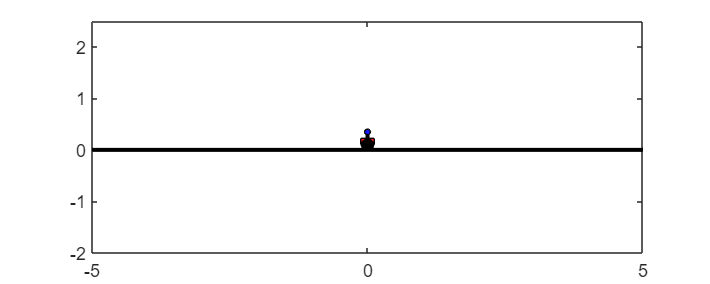

tspan = 0:.001:10;
y0 = [-3; 0; pi+.1; 0];

   % LQR works! 
    [t,y] = ode45(@(t,y)((A-B*K)*(y-[0; 0; pi; 0])),tspan,y0);
 
   % LQG worked!
   %[t,y] = ode45(@(t,y)((Akf-B*Klqg)*(y-[0; 0; pi; 0])),tspan,y0);
 
   % currently cannot solve for in time. look at file for notes
   %[t,y] = ode45(@(t,y)cartpole_ode(y,m,M,L,g,b,-K*(y-[1; 0; pi; 0])),tspan,y0);
    
for k=1:100:length(t)
    drawcartpole(y(k,:),m,M,L);
end